R1=20

R1 = 20

C1=0.000119

C1 = 1.1900e-04

Cc=0.000841

Cc = 8.4100e-04

p=0.1943

p = 0.1943


f_=linspace(1,5,100)

f_ =     1.0000    1.0404    1.0808    1.1212    1.1616    1.2020    1.2424    1.2828    1.3232    1.3636    1.4040    1.4444    1.4848    1.5253    1.5657    1.6061    1.6465    1.6869    1.7273    1.7677    1.8081    1.8485    1.8889    1.9293    1.9697    2.0101    2.0505    2.0909    2.1313    2.1717    2.2121    2.2525    2.2929    2.3333    2.3737    2.4141    2.4545    2.4949    2.5354    2.5758    2.6162    2.6566    2.6970    2.7374    2.7778    2.8182    2.8586    2.8990    2.9394    2.9798


f=10.^f_

f = 1.0e+05 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0011    0.0012    0.0014    0.0015    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0028    0.0031    0.0034    0.0038    0.0041    0.0045    0.0050    0.0055    0.0060    0.0066    0.0072    0.0079    0.0087    0.0095



R2=(p/(1-p))*R1

R2 = 4.8231

C2=((1-p)/p)*C1+Cc/p

C2 = 0.0048

Z=1./(1./R1+2j*pi*f*C1)+1./(1./R2+2j*pi*f*C2)

Z =   21.1009 - 5.1733i  20.8257 - 5.3618i  20.5485 - 5.5608i  20.2672 - 5.7741i  19.9787 - 6.0051i  19.6789 - 6.2564i  19.3628 - 6.5300i  19.0246 - 6.8267i  18.6582 - 7.1460i  18.2568 - 7.4860i  17.8139 - 7.8432i  17.3233 - 8.2124i  16.7794 - 8.5865i  16.1777 - 8.9569i  15.5156 - 9.3131i  14.7927 - 9.6437i  14.0111 - 9.9363i  13.1763 -10.1786i  12.2964 -10.3593i  11.3828 -10.4687i  10.4490 -10.4999i   9.5103 -10.4492i   8.5823 -10.3166i   7.6801 -10.1056i   6.8171 - 9.8233i   6.0047 - 9.4788i   5.2510 - 9.0835i   4.5615 - 8.6491i   3.9386 - 8.1875i   3.3823 - 7.7098i   2.8905 - 7.2260i   2.4598 - 6.7446i   2.0854 - 6.2726i   1.7624 - 5.8154i   1.4853 - 5.3769i   1.2488 - 4.9600i   1.0478 - 4.5665i   0.8777 - 4.1971i   0.7341 - 3.8522i   0.6133 - 3.5313i   0.5118 - 3.2340i   0.4267 - 2.9592i   0.3556 - 2.7059i   0.2961 - 2.4728i   0.2464 - 2.2586i   0.2050 - 2.0622i   0.1705 - 1.8822i   0.1418 - 1.7174i   0.1178 - 1.5666i   0.0979 - 1.4289i


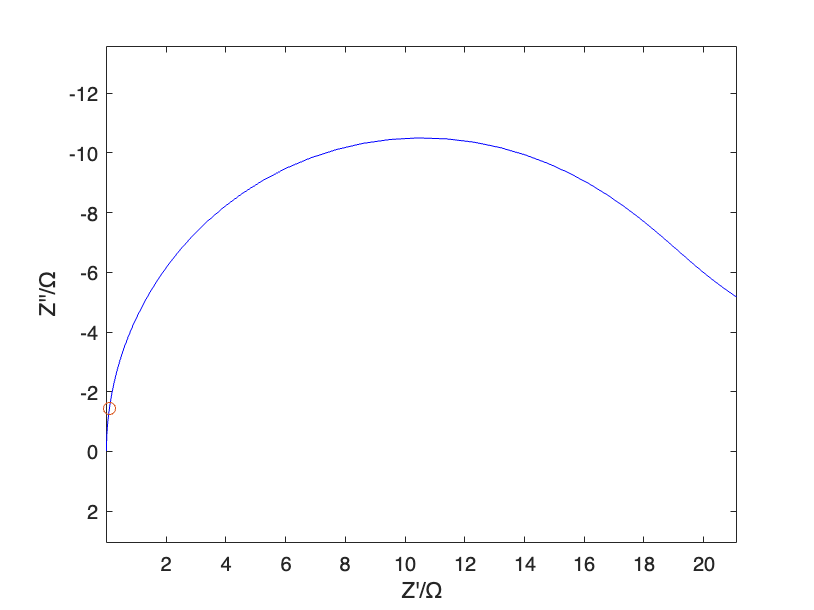



% Zrc=1./(1./R1+1./Zc)+1./(1./R2+1./Zc2)
% Zrc=1./(1./R1+1./Zc+1./(R2+Zc2))
% plotecplx(fd,z,1)
% hold on
% plotecplx(fd,data_20190915_RCRC_0(30,:),1)
% hold off
% plotcplx(Z_w)

plotcplx(Z)
hold on
plot(real(Z(50)),imag(Z(50)),'o')
hold off